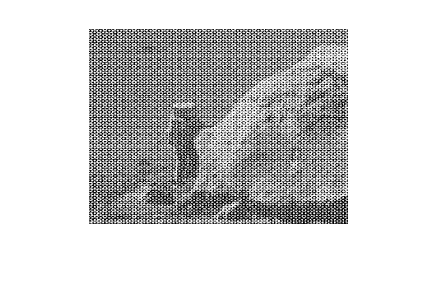


clc;
clear;
close all;
a = imread("1.jpg");
imshow(a)

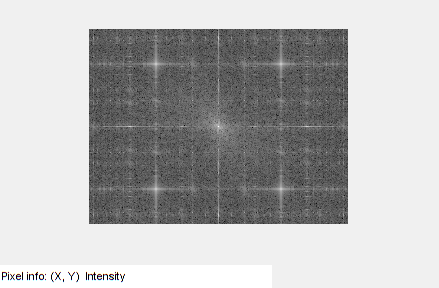

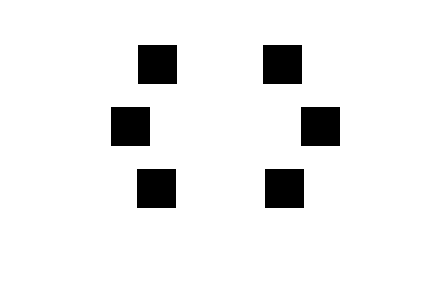

a = rgb2gray(a);
Fshift = fftshift(fft2(double(a)));
figure, imshow(log(abs(Fshift)), []), impixelinfo;
% From inspecting by hand, peaks are at (x,y):
P = [ ...
 194, 36; ...
 69, 36; ...
 68, 160; ...
 196, 160; ...
 42,98;...
 232,98;...
 ];

% Make a mask with zeros at those locations
M = ones(size(a,1), size(a,2));
N = 39;
disk = zeros(N,N);
for i=1:length(P)
 M(P(i,2)-floor(N/2):P(i,2)+floor(N/2), P(i,1)-floor(N/2):P(i,1)+floor(N/2)) = disk(:,:);
end
figure, imshow(M, []);

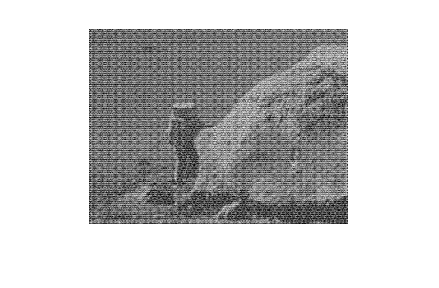

Gshift = M .* Fshift;
G = ifftshift(Gshift);
g = abs(ifft2(G));
figure, imshow(g, []);

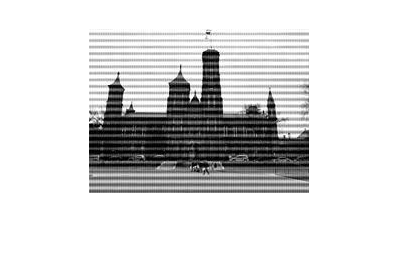


a = imread("2.jpg");
imshow(a)

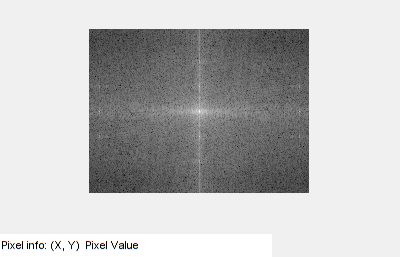

a = rgb2gray(a);
Fshift = fftshift(fft2(double(a)));
figure, imshow(log(abs(Fshift)), []), impixelinfo;

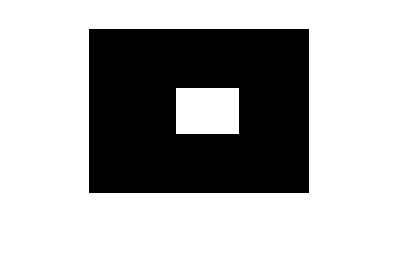

% From inspecting by hand, peaks are at (x,y):
P = [ ...
 109 33; ...
 189, 79; ...
 200 100;...
 43 133;...
 165 30;...
 41 70;...
 ];

% Make a mask with zeros at those locations
M = zeros(size(a,1), size(a,2));
N = 41;
% disk = zeros(N);
% for i=1:length(P)
%  M(P(i,2)-floor(N/2):P(i,2)+floor(N/2), P(i,1)-floor(N/2):P(i,1)+floor(N/2)) = disk(:,:);
% end
M(60:105,88:150) = 1;
figure, imshow(M, []);

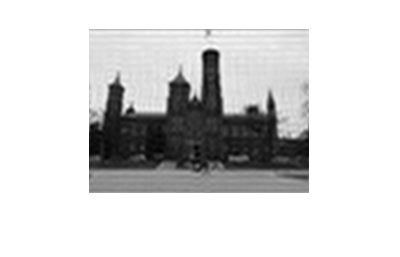

Gshift = M .* Fshift;
G = ifftshift(Gshift);
g = abs(ifft2(G));
figure, imshow(g, []);

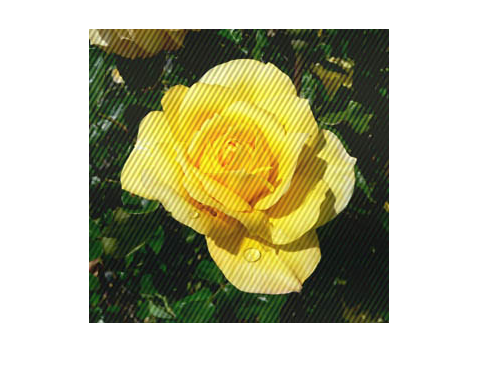



a = imread("3.jpg");
imshow(a)

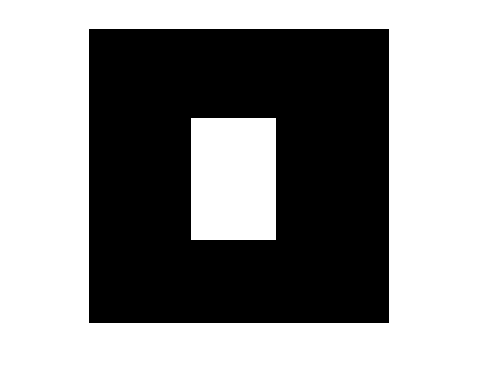

a = rgb2gray(a);
Fshift = fftshift(fft2(double(a)));
figure, imshow(log(abs(Fshift)), []), impixelinfo;
M = zeros(size(a,1), size(a,2));

M(90:211,103:187) = 1;
figure, imshow(M, []);

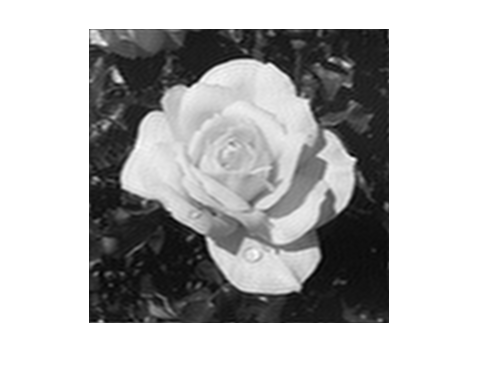

Gshift = M .* Fshift;
G = ifftshift(Gshift);
g = abs(ifft2(G));
figure, imshow(g, []);

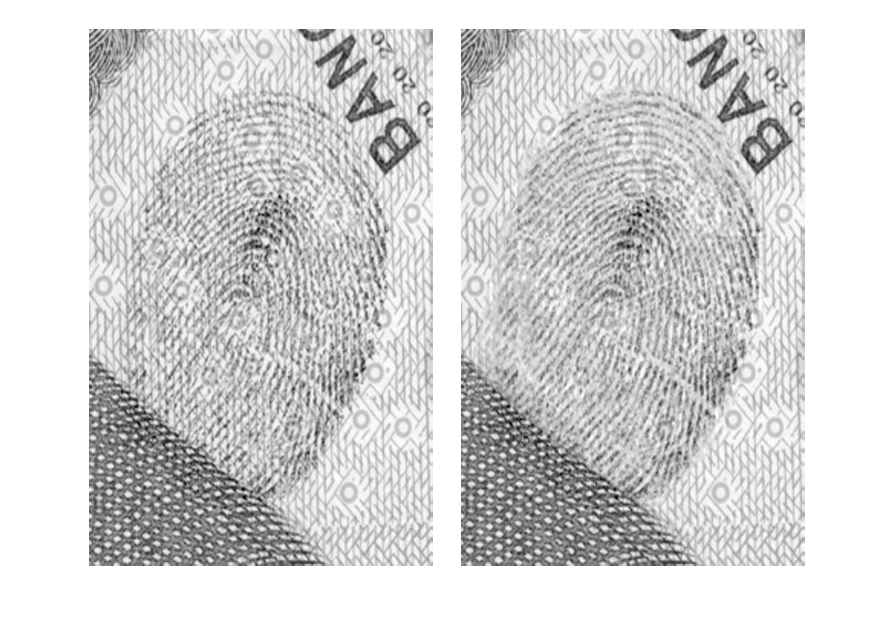


a = imread("4.jpg");
imshow(a)

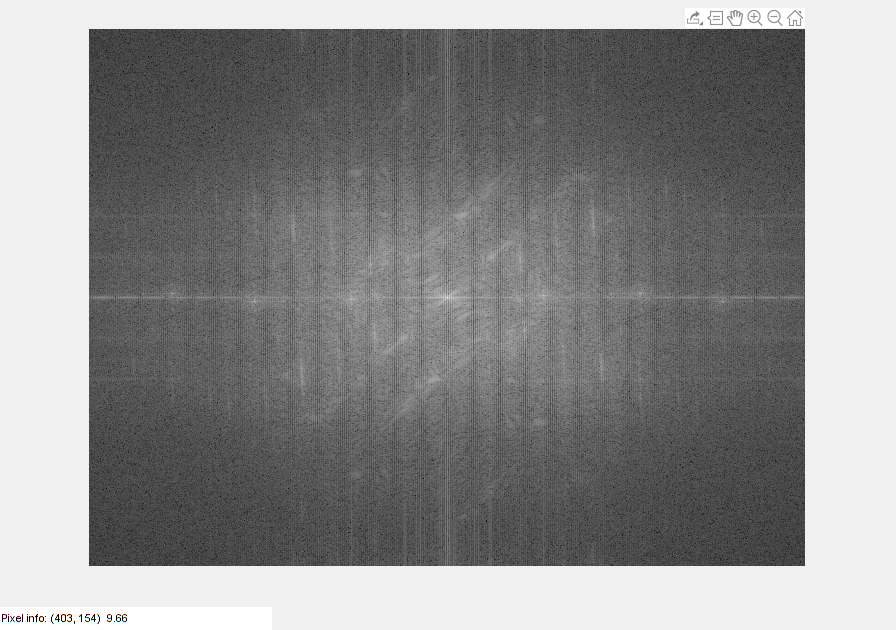

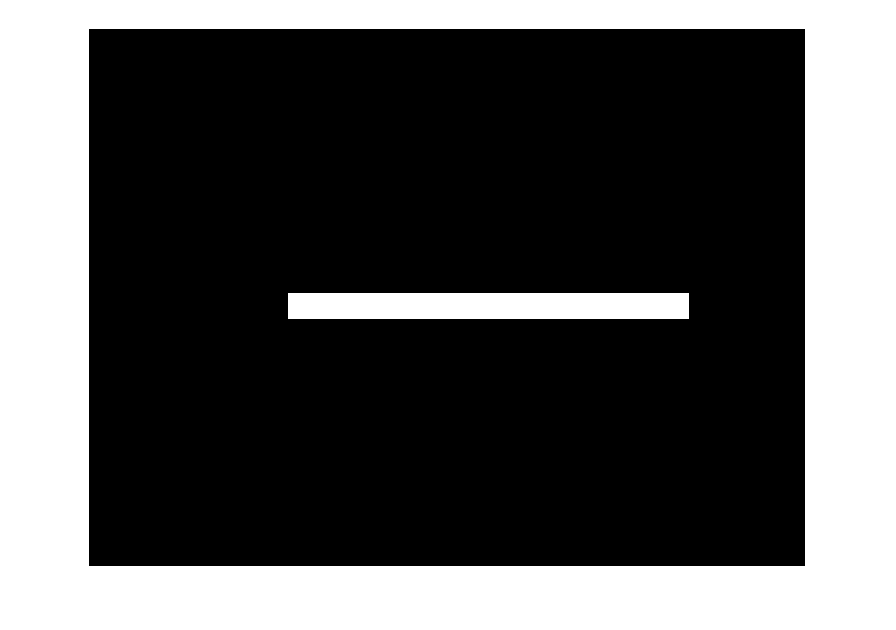

a = rgb2gray(a);
Fshift = fftshift(fft2(double(a)));
figure, imshow(log(abs(Fshift)), []), impixelinfo;
M = zeros(size(a,1), size(a,2));
M(265:290,200:600) = 1;
figure, imshow(M, []);

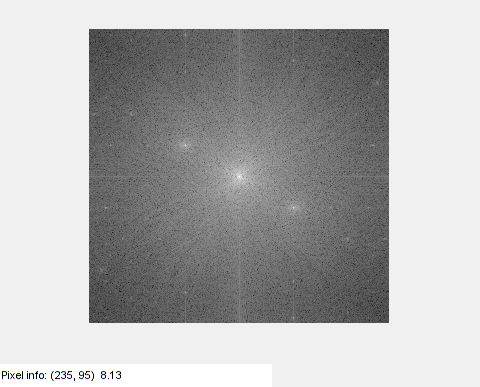

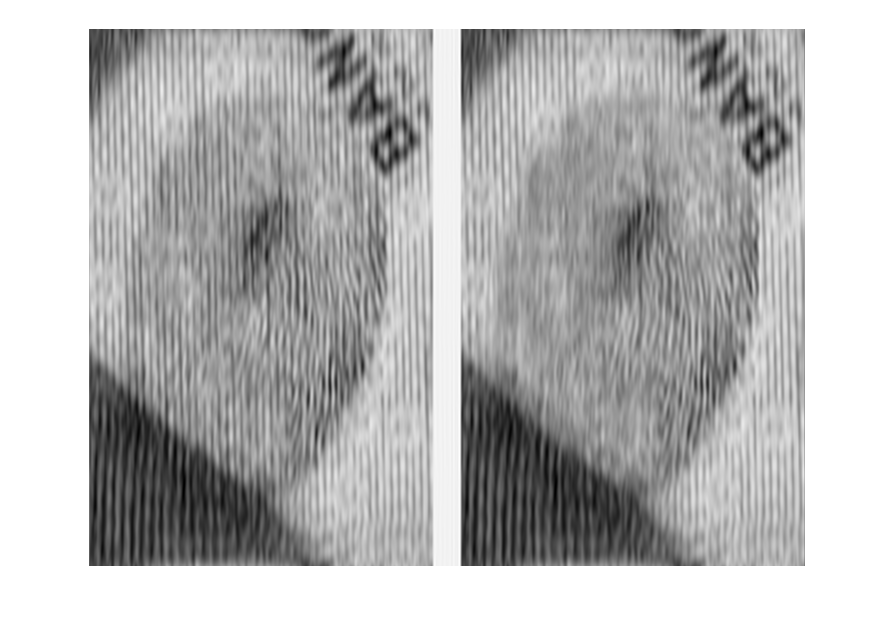

Gshift = M .* Fshift;
G = ifftshift(Gshift);
g = abs(ifft2(G));
figure, imshow(g, []);